# exam 17

## 17.1

rotm = [7,3;3,4]*[1,3;2,2]

rotm =     13    27
    11    17


a = [10;35]

a =     10
    35


b = [29;57]

b =     29
    57


norm(rotm*a-rotm*b)

ans = 1.0233e+03

## 17.4

k = [3, 17, 5, 200, 3, 8, 1, 100, 1, 13, 5, 110, 1, 10, 4, 35, 2, 9];
I = gray_run(5,5,k)

I =     17    17    17   200   200
   200   200   200     8     8
     8   100    13   110   110
   110   110   110    10    35
    35    35    35     9     9


17+8+13+10+9

ans = 57

## 17.6

I = [124,245,193;
    204,167,189;
    36,9,100]

I =    124   245   193
   204   167   189
    36     9   100


I = I./255

I =     0.4863    0.9608    0.7569
    0.8000    0.6549    0.7412
    0.1412    0.0353    0.3922


I = I.^1.28

I =     0.3974    0.9501    0.7001
    0.7515    0.5817    0.6816
    0.0816    0.0138    0.3017


I = I.*255

I =   101.3324  242.2709  178.5180
  191.6441  148.3358  173.7960
   20.8083    3.5286   76.9429


F = [-1,0,1;
    -1,0,1;
    -1,0,1]

F =     -1     0     1
    -1     0     1
    -1     0     1


sum(sum(F.*I))

ans = 115.4722

## 17.7

F = [212,234,192;
    149,73,97;
    140,193,145]

F =    212   234   192
   149    73    97
   140   193   145


A = [203,192,127;
    48,70,245;
    125,173,87]

A =    203   192   127
    48    70   245
   125   173    87


B = [173,87,178;
    167,149,227;
    41,57,245]

B =    173    87   178
   167   149   227
    41    57   245


sum(sum(F.*A))-sum(sum(F.*B))

ans = 10624

## 17.8

mean([-944,-54])

ans = -499

mean([-54,37])

ans = -8.5000

## 17.10

F = [212,234,192;
    149,73,97;
    140,193,145]

F =    212   234   192
   149    73    97
   140   193   145


A = [203,192,127;
    48,70,245;
    125,173,87]

A =    203   192   127
    48    70   245
   125   173    87


B = [173,87,178;
    167,149,227;
    41,57,245]

B =    173    87   178
   167   149   227
    41    57   245


corr1 = norm_corr(F,A)

corr1 = 0.9123

corr2 = norm_corr(F,B)

corr2 = 0.8267

## 17.11

4/7

ans = 0.5714

## 17.12

I = run_length(15,15,[3,3,3,4,4,5,5,7,8,8,9,9,10,10,11,11,11,12,12,12,13],[3,7,13,3,12,3,6,9,2,10,2,11,3,8,3,7,12,3,8,10,10;3,7,13,6,13,4,7,11,2,11,2,12,4,8,4,9,12,3,8,13,12])

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     1     0     0     0     0     0     1     0     0
     0     0     1     1     1     1     0     0     0     0     0     1     1     0     0
     0     0     1     1     0     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0
     0     1     0     0     0     0     0     0     0     1     1     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     1     1     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0


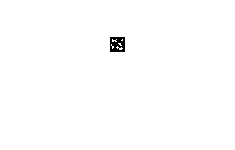

imshow(I)

L = bwlabel(I,4) 

L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     2     0     0     0     4     0     0     0     0     0     8     0     0
     0     0     2     2     2     2     0     0     0     0     0     8     8     0     0
     0     0     2     2     0     2     2     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     6     6     6     0     0     0     0
     0     1     0     0     0     0     0     0     0     6     6     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     6     6     0     0     0
     0     0     3     3     0     0     0     5     0     0     0     0     0     0     0


imshow(L)

A = regionprops(L,'Extent') 

A = 8×1 struct array with fields:
    Extent


## 17.13

I = chaincode([4,3]+1,[0,0,4,5,6,0,6,6,5,5,2,2,1,2,2,2]+1)

I =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     1     0     0     0     0
     0     0     0     0     1     0     0     0     0     0
     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     0     1     0     1     0
     0     0     0     0     0     0     0     1     1     0
     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0


se = strel('disk',1)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


sum(sum(imopen(I,se)))

ans = 5

## 17.14

pix = 8/3200

pix = 0.0025

B = sqrt(416248*(pix^2)*4/pi)

B = 1.8200

B/52*100

ans = 3.5000

## 17.15

5/8

ans = 0.6250

## 17.16

v = blinliner(37.4,23.5,[105,204,232,111])

v = 164.1000

## 17.17

I = [88,66,46,178,167,83;
    149,152,108,163,104,27;
    27,6,24,9,209,156;
    231,108,153,18,183,199;
    224,80,120,81,247,108;
    209,41,177,135,135,23
    ]

I =     88    66    46   178   167    83
   149   152   108   163   104    27
    27     6    24     9   209   156
   231   108   153    18   183   199
   224    80   120    81   247   108
   209    41   177   135   135    23


II = remapping(I,45,210)

II =   101.1411   86.0788   72.3859  162.7593  155.2282   97.7178
  142.9046  144.9585  114.8340  152.4896  112.0954   59.3776
   59.3776   45.0000   57.3237   47.0539  183.9834  147.6971
  199.0456  114.8340  145.6432   53.2158  166.1826  177.1369
  194.2531   95.6639  123.0498   96.3485  210.0000  114.8340
  183.9834   68.9627  162.0747  133.3195  133.3195   56.6390


III = medfilt2(II,[3,3])

III =          0   86.0788   86.0788  112.0954   97.7178         0
   59.3776   86.0788   86.0788  114.8340  147.6971   97.7178
   59.3776  114.8340  114.8340  114.8340  147.6971  112.0954
   59.3776  114.8340   95.6639  123.0498  147.6971  147.6971
   95.6639  145.6432  114.8340  133.3195  133.3195  114.8340
         0   95.6639   95.6639  123.0498   96.3485         0


## 17.18

I = [199,240,209,18,175,237;
    99,244,4,115,47,198;
    62,147,11,139,94,124;
    103,15,43,76,160,111;
    25,60,166,190,199,114;
    34,90,187,48,21,78
    ]

I =    199   240   209    18   175   237
    99   244     4   115    47   198
    62   147    11   139    94   124
   103    15    43    76   160   111
    25    60   166   190   199   114
    34    90   187    48    21    78


[A,T,P,cost] = findpath(I)

A =    199   240   209    18   175   237
   298   443    22   133    65   373
   360   169    33   161   159   189
   272    48    76   109   319   270
    73   108   214   266   308   384
   107   163   295   262   287   386


T =      0     0     0     0     0     0
     1     1     4     4     4     5
     1     3     3     3     5     5
     2     3     3     3     5     5
     2     2     2     3     4     6
     1     1     2     3     4     5


P =      0     0     0     1     0     0
     0     0     1     0     0     0
     0     0     1     0     0     0
     0     1     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0


cost = 301

## 17.19

m1 = mean([52,48,45])

m1 = 48.3333

m2 = mean([33,38,35])

m2 = 35.3333

m3 = mean([221,218,219])

m3 = 219.3333

d1 = mean([m1,m2])

d1 = 41.8333

d2 = mean([m1,m3])

d2 = 133.8333

## 17.20

u = gaussianinter(37,5,53,2.6)

u = 47.0068

## 17.21

T = [65,159,28,45,39,13;
    97,234,189,198,155,75;
    13,97,210,201,203,18;
    9,198,201,196,199,104;
    90,2,28,199,92,1;
    132,57,102,14,169,132]

T =     65   159    28    45    39    13
    97   234   189   198   155    75
    13    97   210   201   203    18
     9   198   201   196   199   104
    90     2    28   199    92     1
   132    57   102    14   169   132


T1 = T>170

T1 = 6×6 logical array
   0   0   0   0   0   0
   0   1   1   1   0   0
   0   0   1   1   1   0
   0   1   1   1   1   0
   0   0   0   1   0   0
   0   0   0   0   0   0


se1 = strel('disk',1);
se2 = strel('square',3);
I1 = imerode(T1,se1)

I1 = 6×6 logical array
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   1   0   0
   0   0   0   1   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0


I2 = imdilate(I1,se2)

I2 = 6×6 logical array
   0   0   0   0   0   0
   0   0   1   1   1   0
   0   0   1   1   1   0
   0   0   1   1   1   0
   0   0   1   1   1   0
   0   0   0   0   0   0


## 17.23

A = [0,222,232;0,22,46;0,102,67]

A =      0   222   232
     0    22    46
     0   102    67


A = [102,106,86;19,13,230;61,230,94]

A =    102   106    86
    19    13   230
    61   230    94


T = [-1,-2,-1;0,0,0;1,2,1]

T =     -1    -2    -1
     0     0     0
     1     2     1


sum(sum(A.*T))

ans = 215

## 17.24

M = run_length(5,5,[1,2,3,4,5],[4,3,2,2,3;4,4,2,2,3])

M =      0     0     0     1     0
     0     0     1     1     0
     0     1     0     0     0
     0     1     0     0     0
     0     0     1     0     0


## 17.25

I = [199,240,209,18,175,237;
    99,244,4,115,47,198;
    62,147,11,139,94,124;
    103,15,43,76,160,111;
    25,60,166,190,199,114;
    34,90,187,48,21,78]

I =    199   240   209    18   175   237
    99   244     4   115    47   198
    62   147    11   139    94   124
   103    15    43    76   160   111
    25    60   166   190   199   114
    34    90   187    48    21    78


[A,T,P,cost] = findpath(I)

A =    199   240   209    18   175   237
   298   443    22   133    65   373
   360   169    33   161   159   189
   272    48    76   109   319   270
    73   108   214   266   308   384
   107   163   295   262   287   386


T =      0     0     0     0     0     0
     1     1     4     4     4     5
     1     3     3     3     5     5
     2     3     3     3     5     5
     2     2     2     3     4     6
     1     1     2     3     4     5


P =      0     0     0     1     0     0
     0     0     1     0     0     0
     0     0     1     0     0     0
     0     1     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0


cost = 301